##   Registrazione voce e analisi

Questo script permette di registrare un nuovo file vocale se necessario. Inoltre viene calcolata e mostrata la TF. 

#### Inizializzazioni

Cancelliamo tutte le variabili in memoria e chiudiamo eventuali figure

clear variables
close all

Definiamo i parametri: la frequenza di campionamento iniziale è di 16 kHz, ed ogni campione è rappresentato su 16 bit. 

% Frequenza di campionamento [campioni/sec]
Fc = 16000; % Hertz

% num. bit per campione
N = 16;

Scegliamo il nome del file

namefile='myvoicerecording16kHz.mat';

#### Registrazione / caricamento

Se esiste un file audio e se non si vuole registrarne uno nuovo, lo si carica. Altrimenti si registra un nuovo file. 

% Se il file non esiste, creare il proprio file
if ~exist(namefile,'file') 
    % registrazione... (è necessario un micro collegato al portatile)
    r = audiorecorder(Fc,N,1);
    disp('Premere un tasto per cominciare la registrazione...')
    pause
    disp('Registrazione in corso. Premere un tasto per terminare')
    record(r);     % parlare ... 
    % l'istruzione "pause" serva l'esecuzione del programma mentre si registra la voce.
    % Esce alla pressione di un tasto
    pause
    stop(r); % stop recording
    disp('Registrazione eseguita. Ecco quanto registrato')
    y = getaudiodata(r, 'double'); % prende i dati in un array di  int16 
    save(namefile,'Fc','y','N')
    p = play(r);   % riproduzione
else % Se il file esiste, lo carica
    load(namefile,'Fc','y','N')
    disp(['Caricamento del file audio con Fc = ',num2str(Fc/1e3), 'KHz'])
end

Premere un tasto per cominciare la registrazione...


Registrazione in corso. Premere un tasto per terminare


Registrazione eseguita. Ecco quanto registrato


#### Calcolo Trasformata di Fourier

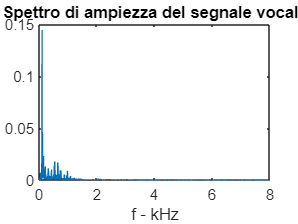

Tc = 1/Fc;
% number of samples in the audiotrace
M = length(y);
% time interval for the audio trace
t =(0:M-1)*Tc;

[Y,F] = CTFT_real(y,Fc);
f = F/1e3; % Passiamo ai kHz

plot(f,Y);
title('Spettro di ampiezza del segnale vocale')
xlabel('f - kHz')

Siccome il segnale è campionato a 16 kHz, con la FFT possiamo visualizzare lo spettro fino alla metà di tale frequenza. In ogni caso, il segnale vocale ha uno spettro concentrato in frequenze più basse: aldilà dei 3kHz c'è poca energia del segnale.

Visualizziamo anche lo spettro di ampiezza in dB:

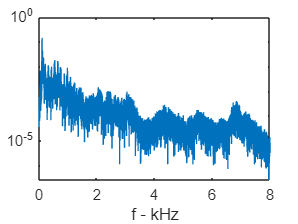

figure;
title('Spettro di ampiezza del segnale vocale, scala logaritmica')
semilogy(f,Y);
xlabel('f - kHz')